cityStrings = ["Berlin", "Paris", "Rome", "Tokyo", "TestSet"];
city = cityStrings(1)

city = "Berlin"

popularity = false

popularity = logical
   0


price = false

price = logical
   0


visiting_time = false

visiting_time = logical
   0



destSights = getCityDataSet(city);
eta = getCityEta(city);

%figure(1);
%text([destSights(:).lat],[destSights(:).long],[destSights(:).name])
%hold on;
%plot([destSights(:).lat],[destSights(:).long],'bo-')


% ST:                           Algorithm Edit Comments
% For variable and param explanation please visit TSP_ACO
%    SETTING PARAMS     %
% exploit vs explore
maxAnalyticsIts = 1010;
analyticsIts = 1;
q_0 = 0.17; % approx. new best at 0.12; 0.17;
numAnts = 50; % approx. new best at 26; 50;
beta = 0.01; %approx. new best at 0.01; 0.01; WHY IS THAT??????????
maxIts = 820; %approx. new best at 950; 820;
%Currently tracking Q
Q = 10; %approx. new best at 14; 21; 77; ?!
rho = 0.43; %approx. new best at 0.22; 0.35; 0.48; 0.43
paramScores = zeros([1, 100]);
paramValues = zeros([1, 100]);
%Smaller array to avg the ten iterations per 
avgScores = zeros([1, 10]);
avgCount = 1;

while analyticsIts < maxAnalyticsIts

    %Change the parameter by a small value every tenth iteration
    if(mod(analyticsIts, 10) == 0)
        scoreAvg = sum(avgScores) / length(avgScores)
        paramScores(analyticsIts / 10) = scoreAvg;
        paramValues(analyticsIts / 10) = Q;

        avgScores = zeros([1, 10]);
        avgCount = 1;

        Q = Q + 10
    end

    %Set param in the analytic matrix for this iteration
    %paramScores(1,analyticsIts) = numAnts;

params = struct('q_0', q_0, 'numAnts', numAnts, 'beta', beta, 'Q', Q, 'rho', rho);
%fprintf('Running ' + city + ' Sightseeing Optimization on  %i Sights with the following parameters:\n', length(destSights));
%disp(params);
tau = ones(length(destSights),length(destSights));
bestPath = 1:length(destSights);
bestScore = newScorePath(0, bestPath, destSights, eta);
%fprintf('Initial Score: %f', bestScore);
numIts = 1;
scores = zeros(1, maxIts);

    while numIts < maxIts;
	    for ant_k = 1:numAnts
		    
		    path = zeros(1, length(destSights));
		    currInd = 1;
		    path(currInd) = randi(length(destSights));
		    unvisited = 1:length(destSights);
		    unvisited(path(1)) = [];
		    
		    for currInd = 1:(length(destSights) - 1)
			    r = path(currInd);

			    if (rand < q_0)
				    [~, sInd] = max(tau(r, unvisited) .* eta(r, unvisited).^beta);
				    s = unvisited(sInd);
			    else
				    vec = tau(r, unvisited) .* (eta(r, unvisited).^beta);
				    probs = vec ./ sum(vec);

				    if any(isnan(probs))
					    sInd = 1;
                    else
					    sInd = find(cumsum(probs) > rand, 1);
				    end
				    s = unvisited(sInd);
			    end

			    path(currInd + 1) =  s;
			    unvisited(sInd) = [];
		    end
		    
		    score = newScorePath(0, path, destSights, eta);
		    if (score < bestScore)
			    bestScore = score;
			    bestPath = path;
		    end

		    toCities = circshift(path, [0,1]);
		    
		    for ind = 1:length(destSights)
			    fromCity = path(ind);
			    toCity = toCities(ind);
			    tau(fromCity, toCity) = tau(fromCity, toCity) + Q / score;
		    end
        end
	    scores(numIts) = bestScore;
	    tau = (1 - rho) * tau;
	    
	    numIts = numIts + 1;
    end

    disp("Best Score: " + bestScore);
    avgScores(avgCount) = bestScore;
    analyticsIts = analyticsIts + 1;
    avgCount = avgCount + 1;

end

Best Score: 103
Best Score: 105
Best Score: 103
Best Score: 106
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 105


scoreAvg = 93.4000

Q = 20

Best Score: 109
Best Score: 105
Best Score: 108
Best Score: 107
Best Score: 104
Best Score: 108
Best Score: 108
Best Score: 104
Best Score: 104
Best Score: 103


scoreAvg = 106

Q = 30

Best Score: 104
Best Score: 106
Best Score: 103
Best Score: 107
Best Score: 106
Best Score: 105
Best Score: 103
Best Score: 109
Best Score: 105
Best Score: 104


scoreAvg = 105.2000

Q = 40

Best Score: 105
Best Score: 105
Best Score: 105
Best Score: 103
Best Score: 105
Best Score: 103
Best Score: 105
Best Score: 106
Best Score: 103
Best Score: 103


scoreAvg = 104.3000

Q = 50

Best Score: 109
Best Score: 103
Best Score: 109
Best Score: 108
Best Score: 106
Best Score: 106
Best Score: 109
Best Score: 104
Best Score: 110
Best Score: 103


scoreAvg = 106.7000

Q = 60

Best Score: 103
Best Score: 107
Best Score: 106
Best Score: 109
Best Score: 103
Best Score: 103
Best Score: 108
Best Score: 111
Best Score: 103
Best Score: 106


scoreAvg = 105.9000

Q = 70

Best Score: 105
Best Score: 103
Best Score: 104
Best Score: 104
Best Score: 105
Best Score: 106
Best Score: 103
Best Score: 103
Best Score: 104
Best Score: 103


scoreAvg = 104

Q = 80

Best Score: 104
Best Score: 110
Best Score: 106
Best Score: 106
Best Score: 106
Best Score: 107
Best Score: 103
Best Score: 110
Best Score: 109
Best Score: 105


scoreAvg = 106.6000

Q = 90

Best Score: 103
Best Score: 106
Best Score: 104
Best Score: 105
Best Score: 103
Best Score: 107
Best Score: 103
Best Score: 105
Best Score: 107
Best Score: 103


scoreAvg = 104.6000

Q = 100

Best Score: 103
Best Score: 106
Best Score: 105
Best Score: 105
Best Score: 103
Best Score: 103
Best Score: 109
Best Score: 106
Best Score: 106
Best Score: 103


scoreAvg = 104.9000

Q = 110

Best Score: 103
Best Score: 110
Best Score: 103
Best Score: 108
Best Score: 105
Best Score: 106
Best Score: 103
Best Score: 106
Best Score: 105
Best Score: 103


scoreAvg = 105.2000

Q = 120

Best Score: 104
Best Score: 107
Best Score: 103
Best Score: 105
Best Score: 103
Best Score: 105
Best Score: 106
Best Score: 103
Best Score: 105
Best Score: 103


scoreAvg = 104.4000

Q = 130

Best Score: 105
Best Score: 108
Best Score: 108
Best Score: 105
Best Score: 104
Best Score: 107
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 104.9000

Q = 140

Best Score: 106
Best Score: 104
Best Score: 106
Best Score: 108
Best Score: 106
Best Score: 103
Best Score: 104
Best Score: 107
Best Score: 108
Best Score: 107


scoreAvg = 105.9000

Q = 150

Best Score: 106
Best Score: 106
Best Score: 109
Best Score: 103
Best Score: 109
Best Score: 107
Best Score: 103
Best Score: 108
Best Score: 107
Best Score: 105


scoreAvg = 106.3000

Q = 160

Best Score: 108
Best Score: 104
Best Score: 104
Best Score: 105
Best Score: 107
Best Score: 105
Best Score: 105
Best Score: 107
Best Score: 106
Best Score: 106


scoreAvg = 105.7000

Q = 170

Best Score: 103
Best Score: 105
Best Score: 105
Best Score: 108
Best Score: 103
Best Score: 108
Best Score: 104
Best Score: 104
Best Score: 103
Best Score: 105


scoreAvg = 104.8000

Q = 180

Best Score: 108
Best Score: 106
Best Score: 106
Best Score: 106
Best Score: 105
Best Score: 103
Best Score: 104
Best Score: 106
Best Score: 106
Best Score: 107


scoreAvg = 105.7000

Q = 190

Best Score: 108
Best Score: 105
Best Score: 103
Best Score: 104
Best Score: 105
Best Score: 104
Best Score: 103
Best Score: 106
Best Score: 103
Best Score: 104


scoreAvg = 104.5000

Q = 200

Best Score: 106
Best Score: 104
Best Score: 105
Best Score: 103
Best Score: 103
Best Score: 107
Best Score: 108
Best Score: 103
Best Score: 103
Best Score: 106


scoreAvg = 104.8000

Q = 210

Best Score: 104
Best Score: 106
Best Score: 105
Best Score: 105
Best Score: 105
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 106
Best Score: 108


scoreAvg = 104.8000

Q = 220

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 106
Best Score: 103
Best Score: 103
Best Score: 106
Best Score: 103
Best Score: 104
Best Score: 103


scoreAvg = 103.7000

Q = 230

Best Score: 106
Best Score: 107
Best Score: 106
Best Score: 106
Best Score: 109
Best Score: 103
Best Score: 107
Best Score: 103
Best Score: 109
Best Score: 109


scoreAvg = 106.5000

Q = 240

Best Score: 103
Best Score: 107
Best Score: 106
Best Score: 105
Best Score: 106
Best Score: 105
Best Score: 107
Best Score: 106
Best Score: 103
Best Score: 106


scoreAvg = 105.4000

Q = 250

Best Score: 105
Best Score: 106
Best Score: 111
Best Score: 104
Best Score: 103
Best Score: 106
Best Score: 108
Best Score: 103
Best Score: 105
Best Score: 103


scoreAvg = 105.4000

Q = 260

Best Score: 108
Best Score: 103
Best Score: 105
Best Score: 105
Best Score: 103
Best Score: 106
Best Score: 104
Best Score: 106
Best Score: 103
Best Score: 103


scoreAvg = 104.6000

Q = 270

Best Score: 106
Best Score: 107
Best Score: 105
Best Score: 106
Best Score: 106
Best Score: 103
Best Score: 103
Best Score: 106
Best Score: 103
Best Score: 103


scoreAvg = 104.8000

Q = 280

Best Score: 106
Best Score: 107
Best Score: 106
Best Score: 106
Best Score: 106
Best Score: 105
Best Score: 105
Best Score: 103
Best Score: 106
Best Score: 103


scoreAvg = 105.3000

Q = 290

Best Score: 106
Best Score: 103
Best Score: 103
Best Score: 109
Best Score: 106
Best Score: 103
Best Score: 105
Best Score: 105
Best Score: 103
Best Score: 106


scoreAvg = 104.9000

Q = 300

Best Score: 106
Best Score: 103
Best Score: 108
Best Score: 103
Best Score: 106
Best Score: 103
Best Score: 104
Best Score: 103
Best Score: 103
Best Score: 106


scoreAvg = 104.5000

Q = 310

Best Score: 105
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 109
Best Score: 106
Best Score: 106
Best Score: 107
Best Score: 104


scoreAvg = 104.9000

Q = 320

Best Score: 104
Best Score: 108
Best Score: 106
Best Score: 105
Best Score: 106
Best Score: 105
Best Score: 103
Best Score: 105
Best Score: 105
Best Score: 107


scoreAvg = 105.4000

Q = 330

Best Score: 106
Best Score: 103
Best Score: 106
Best Score: 108
Best Score: 106
Best Score: 109
Best Score: 109
Best Score: 104
Best Score: 105
Best Score: 107


scoreAvg = 106.3000

Q = 340

Best Score: 103
Best Score: 105
Best Score: 105
Best Score: 106
Best Score: 103
Best Score: 106
Best Score: 105
Best Score: 104
Best Score: 103
Best Score: 105


scoreAvg = 104.5000

Q = 350

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 108
Best Score: 107
Best Score: 103
Best Score: 106
Best Score: 106
Best Score: 108
Best Score: 106


scoreAvg = 105.3000

Q = 360

Best Score: 103
Best Score: 105
Best Score: 107
Best Score: 106
Best Score: 103
Best Score: 107
Best Score: 103
Best Score: 107
Best Score: 105
Best Score: 106


scoreAvg = 105.2000

Q = 370

Best Score: 105
Best Score: 103
Best Score: 108
Best Score: 106
Best Score: 104
Best Score: 109
Best Score: 105
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 104.9000

Q = 380

Best Score: 106
Best Score: 106
Best Score: 106
Best Score: 103
Best Score: 107
Best Score: 106
Best Score: 107
Best Score: 107
Best Score: 111
Best Score: 110


scoreAvg = 106.9000

Q = 390

Best Score: 108
Best Score: 107
Best Score: 108
Best Score: 103
Best Score: 103
Best Score: 104
Best Score: 105
Best Score: 103
Best Score: 103
Best Score: 105


scoreAvg = 104.9000

Q = 400

Best Score: 105
Best Score: 106
Best Score: 106
Best Score: 105
Best Score: 103
Best Score: 103
Best Score: 104
Best Score: 106
Best Score: 104
Best Score: 106


scoreAvg = 104.8000

Q = 410

Best Score: 109
Best Score: 103
Best Score: 108
Best Score: 104
Best Score: 105
Best Score: 106
Best Score: 109
Best Score: 103
Best Score: 104
Best Score: 103


scoreAvg = 105.4000

Q = 420

Best Score: 106
Best Score: 106
Best Score: 103
Best Score: 105
Best Score: 103
Best Score: 109
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 106


scoreAvg = 104.7000

Q = 430

Best Score: 104
Best Score: 106
Best Score: 109
Best Score: 103
Best Score: 103
Best Score: 105
Best Score: 106
Best Score: 106
Best Score: 108
Best Score: 107


scoreAvg = 105.7000

Q = 440

Best Score: 103
Best Score: 106
Best Score: 106
Best Score: 106
Best Score: 106
Best Score: 103
Best Score: 106
Best Score: 107
Best Score: 106
Best Score: 103


scoreAvg = 105.2000

Q = 450

Best Score: 108
Best Score: 104
Best Score: 109
Best Score: 106
Best Score: 103
Best Score: 106
Best Score: 103
Best Score: 108
Best Score: 109
Best Score: 103


scoreAvg = 105.9000

Q = 460

Best Score: 103
Best Score: 106
Best Score: 106
Best Score: 103
Best Score: 108
Best Score: 107
Best Score: 106
Best Score: 108
Best Score: 103
Best Score: 105


scoreAvg = 105.5000

Q = 470

Best Score: 107
Best Score: 104
Best Score: 108
Best Score: 106
Best Score: 103
Best Score: 106
Best Score: 104
Best Score: 104
Best Score: 106
Best Score: 106


scoreAvg = 105.4000

Q = 480

Best Score: 106
Best Score: 106
Best Score: 103
Best Score: 108
Best Score: 103
Best Score: 106
Best Score: 106
Best Score: 106
Best Score: 106
Best Score: 105


scoreAvg = 105.5000

Q = 490

Best Score: 107
Best Score: 106
Best Score: 106
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 104
Best Score: 110
Best Score: 103
Best Score: 106


scoreAvg = 105.1000

Q = 500

Best Score: 103
Best Score: 103
Best Score: 106
Best Score: 103
Best Score: 107
Best Score: 103
Best Score: 105
Best Score: 108
Best Score: 105
Best Score: 109


scoreAvg = 105.2000

Q = 510

Best Score: 105
Best Score: 105
Best Score: 103
Best Score: 108
Best Score: 103
Best Score: 105
Best Score: 103
Best Score: 105
Best Score: 104
Best Score: 103


scoreAvg = 104.4000

Q = 520

Best Score: 105
Best Score: 106
Best Score: 103
Best Score: 103
Best Score: 108
Best Score: 107
Best Score: 105
Best Score: 105
Best Score: 107
Best Score: 103


scoreAvg = 105.2000

Q = 530

Best Score: 104
Best Score: 109
Best Score: 105
Best Score: 106
Best Score: 107
Best Score: 103
Best Score: 107
Best Score: 107
Best Score: 105
Best Score: 106


scoreAvg = 105.9000

Q = 540

Best Score: 106
Best Score: 103
Best Score: 104
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 109
Best Score: 109
Best Score: 106
Best Score: 103


scoreAvg = 104.9000

Q = 550

Best Score: 107
Best Score: 103
Best Score: 104
Best Score: 106
Best Score: 106
Best Score: 105
Best Score: 103
Best Score: 104
Best Score: 106
Best Score: 105


scoreAvg = 104.9000

Q = 560

Best Score: 107
Best Score: 103
Best Score: 105
Best Score: 103
Best Score: 103
Best Score: 108
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 106


scoreAvg = 104.4000

Q = 570

Best Score: 107
Best Score: 108
Best Score: 103
Best Score: 105
Best Score: 105
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 104.3000

Q = 580

Best Score: 103
Best Score: 106
Best Score: 106
Best Score: 109
Best Score: 105
Best Score: 109
Best Score: 105
Best Score: 107
Best Score: 106
Best Score: 103


scoreAvg = 105.9000

Q = 590

Best Score: 103
Best Score: 103
Best Score: 106
Best Score: 103
Best Score: 105
Best Score: 107
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 106


scoreAvg = 104.2000

Q = 600

Best Score: 103
Best Score: 105
Best Score: 103
Best Score: 108
Best Score: 103
Best Score: 109
Best Score: 103
Best Score: 103
Best Score: 106
Best Score: 103


scoreAvg = 104.6000

Q = 610

Best Score: 103
Best Score: 104
Best Score: 109
Best Score: 105
Best Score: 103
Best Score: 105
Best Score: 108
Best Score: 106
Best Score: 107
Best Score: 106


scoreAvg = 105.6000

Q = 620

Best Score: 104
Best Score: 106
Best Score: 106
Best Score: 103
Best Score: 103
Best Score: 105
Best Score: 105
Best Score: 106
Best Score: 105
Best Score: 106


scoreAvg = 104.9000

Q = 630

Best Score: 106
Best Score: 106
Best Score: 105
Best Score: 106
Best Score: 108
Best Score: 104
Best Score: 103
Best Score: 104
Best Score: 105
Best Score: 105


scoreAvg = 105.2000

Q = 640

Best Score: 110
Best Score: 106
Best Score: 107
Best Score: 108
Best Score: 105
Best Score: 104
Best Score: 107
Best Score: 105
Best Score: 108
Best Score: 106


scoreAvg = 106.6000

Q = 650

Best Score: 105
Best Score: 106
Best Score: 103
Best Score: 107
Best Score: 103
Best Score: 105
Best Score: 104
Best Score: 106
Best Score: 108
Best Score: 107


scoreAvg = 105.4000

Q = 660

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 104
Best Score: 108
Best Score: 107
Best Score: 103
Best Score: 103


scoreAvg = 104

Q = 670

Best Score: 105
Best Score: 107
Best Score: 106
Best Score: 106
Best Score: 105
Best Score: 106
Best Score: 106
Best Score: 109
Best Score: 105
Best Score: 105


scoreAvg = 106

Q = 680

Best Score: 106
Best Score: 103
Best Score: 104
Best Score: 108
Best Score: 106
Best Score: 108
Best Score: 105
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 104.9000

Q = 690

Best Score: 106
Best Score: 104
Best Score: 109
Best Score: 105
Best Score: 103
Best Score: 103
Best Score: 108
Best Score: 109
Best Score: 106
Best Score: 106


scoreAvg = 105.9000

Q = 700

Best Score: 108
Best Score: 105
Best Score: 103
Best Score: 103
Best Score: 106
Best Score: 109
Best Score: 104
Best Score: 103
Best Score: 105
Best Score: 103


scoreAvg = 104.9000

Q = 710

Best Score: 105
Best Score: 103
Best Score: 105
Best Score: 103
Best Score: 105
Best Score: 106
Best Score: 107
Best Score: 109
Best Score: 108
Best Score: 105


scoreAvg = 105.6000

Q = 720

Best Score: 103
Best Score: 105
Best Score: 106
Best Score: 105
Best Score: 105
Best Score: 108
Best Score: 104
Best Score: 107
Best Score: 108
Best Score: 107


scoreAvg = 105.8000

Q = 730

Best Score: 105
Best Score: 103
Best Score: 106
Best Score: 105
Best Score: 103
Best Score: 104
Best Score: 103
Best Score: 107
Best Score: 104
Best Score: 103


scoreAvg = 104.3000

Q = 740

Best Score: 106
Best Score: 106
Best Score: 105
Best Score: 103
Best Score: 110
Best Score: 108
Best Score: 104
Best Score: 103
Best Score: 111
Best Score: 106


scoreAvg = 106.2000

Q = 750

Best Score: 106
Best Score: 106
Best Score: 103
Best Score: 108
Best Score: 106
Best Score: 106
Best Score: 106
Best Score: 105
Best Score: 106
Best Score: 106


scoreAvg = 105.8000

Q = 760

Best Score: 103
Best Score: 106
Best Score: 103
Best Score: 109
Best Score: 109
Best Score: 106
Best Score: 103
Best Score: 103
Best Score: 105
Best Score: 103


scoreAvg = 105

Q = 770

Best Score: 109
Best Score: 105
Best Score: 103
Best Score: 107
Best Score: 107
Best Score: 108
Best Score: 103
Best Score: 105
Best Score: 107
Best Score: 108


scoreAvg = 106.2000

Q = 780

Best Score: 108
Best Score: 105
Best Score: 103
Best Score: 108
Best Score: 104
Best Score: 110
Best Score: 105
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 105.2000

Q = 790

Best Score: 109
Best Score: 106
Best Score: 103
Best Score: 103
Best Score: 105
Best Score: 107
Best Score: 103
Best Score: 107
Best Score: 105
Best Score: 103


scoreAvg = 105.1000

Q = 800

Best Score: 105
Best Score: 110
Best Score: 104
Best Score: 106
Best Score: 106
Best Score: 103
Best Score: 103
Best Score: 105
Best Score: 107
Best Score: 103


scoreAvg = 105.2000

Q = 810

Best Score: 107
Best Score: 105
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 104
Best Score: 106
Best Score: 109
Best Score: 106


scoreAvg = 104.9000

Q = 820

Best Score: 105
Best Score: 107
Best Score: 103
Best Score: 105
Best Score: 103
Best Score: 106
Best Score: 106
Best Score: 106
Best Score: 103
Best Score: 105


scoreAvg = 104.9000

Q = 830

Best Score: 105
Best Score: 103
Best Score: 107
Best Score: 105
Best Score: 103
Best Score: 109
Best Score: 108
Best Score: 106
Best Score: 105
Best Score: 108


scoreAvg = 105.9000

Q = 840

Best Score: 106
Best Score: 103
Best Score: 105
Best Score: 103
Best Score: 103
Best Score: 106
Best Score: 106
Best Score: 106
Best Score: 106
Best Score: 104


scoreAvg = 104.8000

Q = 850

Best Score: 106
Best Score: 103
Best Score: 109
Best Score: 104
Best Score: 106
Best Score: 106
Best Score: 104
Best Score: 103
Best Score: 106
Best Score: 104


scoreAvg = 105.1000

Q = 860

Best Score: 110
Best Score: 106
Best Score: 107
Best Score: 106
Best Score: 105
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 108
Best Score: 103


scoreAvg = 105.4000

Q = 870

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 105
Best Score: 103
Best Score: 108
Best Score: 105
Best Score: 104
Best Score: 103
Best Score: 103


scoreAvg = 104

Q = 880

Best Score: 105
Best Score: 103
Best Score: 105
Best Score: 103
Best Score: 104
Best Score: 103
Best Score: 104
Best Score: 105
Best Score: 107
Best Score: 103


scoreAvg = 104.2000

Q = 890

Best Score: 104
Best Score: 108
Best Score: 109
Best Score: 103
Best Score: 106
Best Score: 105
Best Score: 103
Best Score: 108
Best Score: 103
Best Score: 109


scoreAvg = 105.8000

Q = 900

Best Score: 104
Best Score: 103
Best Score: 103
Best Score: 108
Best Score: 103
Best Score: 105
Best Score: 106
Best Score: 109
Best Score: 104
Best Score: 105


scoreAvg = 105

Q = 910

Best Score: 105
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 107
Best Score: 107
Best Score: 103
Best Score: 103
Best Score: 108
Best Score: 103


scoreAvg = 104.5000

Q = 920

Best Score: 106
Best Score: 107
Best Score: 108
Best Score: 103
Best Score: 104
Best Score: 103
Best Score: 104
Best Score: 103
Best Score: 103
Best Score: 108


scoreAvg = 104.9000

Q = 930

Best Score: 103
Best Score: 106
Best Score: 108
Best Score: 104
Best Score: 105
Best Score: 106
Best Score: 104
Best Score: 106
Best Score: 106
Best Score: 106


scoreAvg = 105.4000

Q = 940

Best Score: 105
Best Score: 107
Best Score: 108
Best Score: 107
Best Score: 108
Best Score: 109
Best Score: 107
Best Score: 105
Best Score: 105
Best Score: 105


scoreAvg = 106.6000

Q = 950

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 105
Best Score: 106
Best Score: 107
Best Score: 106
Best Score: 105
Best Score: 108
Best Score: 103


scoreAvg = 104.9000

Q = 960

Best Score: 105
Best Score: 105
Best Score: 104
Best Score: 106
Best Score: 105
Best Score: 103
Best Score: 107
Best Score: 106
Best Score: 106
Best Score: 103


scoreAvg = 105

Q = 970

Best Score: 105
Best Score: 103
Best Score: 107
Best Score: 107
Best Score: 104
Best Score: 108
Best Score: 108
Best Score: 105
Best Score: 103
Best Score: 104


scoreAvg = 105.4000

Q = 980

Best Score: 106
Best Score: 103
Best Score: 108
Best Score: 103
Best Score: 103
Best Score: 108
Best Score: 106
Best Score: 105
Best Score: 103
Best Score: 104


scoreAvg = 104.9000

Q = 990

Best Score: 103
Best Score: 107
Best Score: 103
Best Score: 108
Best Score: 103
Best Score: 103
Best Score: 104
Best Score: 103
Best Score: 109
Best Score: 103


scoreAvg = 104.6000

Q = 1000

Best Score: 103
Best Score: 104
Best Score: 104
Best Score: 106
Best Score: 110
Best Score: 104
Best Score: 103
Best Score: 105
Best Score: 103
Best Score: 104


scoreAvg = 104.6000

Q = 1010

Best Score: 106
Best Score: 103
Best Score: 106
Best Score: 105
Best Score: 108
Best Score: 106
Best Score: 106
Best Score: 104
Best Score: 107
Best Score: 105


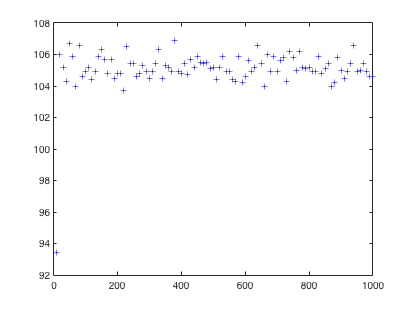


figure(1);
plot(paramValues,paramScores, 'b+');